Setup

A = load('MatlabGiven/mat1.txt');
sol = sort(eig(A), 'descend');

QR iteratie zonder shifts

[E1, res_zonder] = qr_zondershift(A);
norm_res_zonder = zeros(size(res_zonder, 2), 1);
for i = 1:size(res_zonder,2)
    norm_res_zonder(i) = norm(res_zonder(:, i));
end

QR iteratie  met Rayleigh quotient shift

[E2, res_ray] = qr_rayleighshift(A);
norm_res_ray = zeros(size(res_ray, 2), 1);
for i = 1:size(res_ray, 2)
    norm_res_ray(i) = norm(res_ray(:, i));
end

QR iteratie met Wilkinson shift

[E3, res_wilk] = qr_wilkinsonshift(A);
norm_res_wilk = zeros(size(res_wilk, 2), 1);
for i = 1:size(res_wilk, 2)
    norm_res_wilk(i) = norm(res_wilk(:, i));
end

Plotten

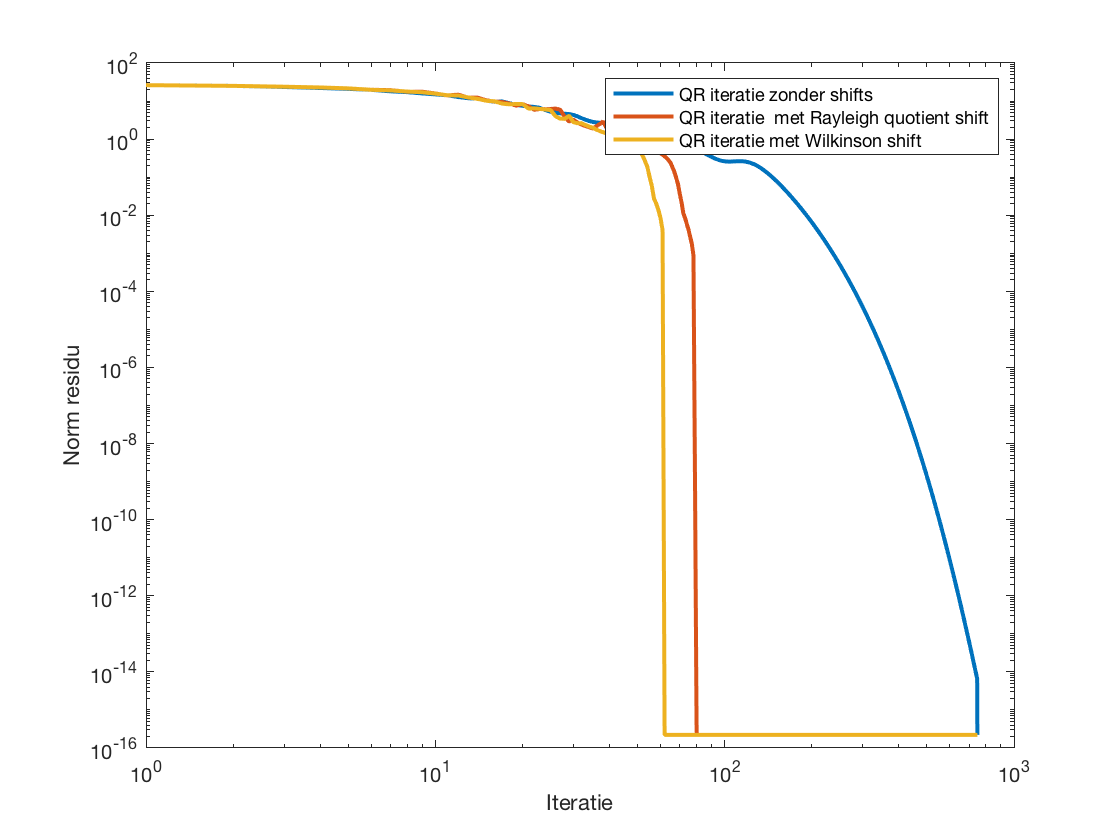

norm_res_zonder(end) = eps;
for i = 1:size(norm_res_ray, 1)
    if norm_res_ray(i) == 0
        norm_res_ray(i) = eps;
    end
end
for i = size(norm_res_ray, 1):size(norm_res_zonder)
    norm_res_ray(i) = eps;
end
for i = 1:size(norm_res_wilk, 1)
    if norm_res_wilk(i) == 0
        norm_res_wilk(i) = eps;
    end
end
for i = size(norm_res_wilk, 1):size(norm_res_zonder)
    norm_res_wilk(i) = eps;
end

figure
loglog(norm_res_zonder, 'linewidth', 2);
hold on;
loglog(norm_res_ray, 'linewidth', 2);
loglog(norm_res_wilk, 'linewidth', 2);
legend('QR iteratie zonder shifts', 'QR iteratie  met Rayleigh quotient shift', 'QR iteratie met Wilkinson shift');
xlabel('Iteratie');
ylabel('Norm residu');